# Outer VRFT ?

Having tuned the inner controller we can move on to the next step: tuning the outer controller. Thi time too we will be using a second order system as our reference model. We will however choose a much lower bandwidth.

load 'quad_copter_models.mat';


outer_bw = 4; % Still works with d = .4
outer_damp = .3;

% Minimises the difference between the step responses of the Hinf and VRFT controllers
OuterReferenceModel = mk_2nd_order(outer_bw, outer_damp);
OuterReferenceModel_dt = c2d(OuterReferenceModel, Ts);

## VRFT Time - Calculating The Reference Signal

In the cascade VRFT algorithm the first step of the outer loop tuning is to build the reference input. When we tune the inner loop the plant input is also the output of the controller and the problem is reduced to finding a controller that would create that signal. 

When we move to the outer loop the first step is to reconstruct a reference signal. The output of the outer controller is also the sum of the feedback and the error signal. These are both known by now. 

The feedback signal is simply the output of the plant used in to tune the inner loop whilst the error can be calculated by inverting the inner controller and multiplying it by the input of the plant, also used in the previous step. Thus:


$$r_i(t) = C^{-1}(z) \cdot u(t) + y_i(t) $$


and if we substitute $C$, $u$ and $y$ with our variables we have:


$$r_i(t) = R^{-1}_i(z) \cdot \delta M + \dot{q}$$


% I/O Signals
Ri_inv = OptimalInnerController^-1;

ei = lsim(Ri_inv, vrft_data.dM, vrft_data.time); 
ri = ei + vrft_data.q_dot;

Let's see what this looks like

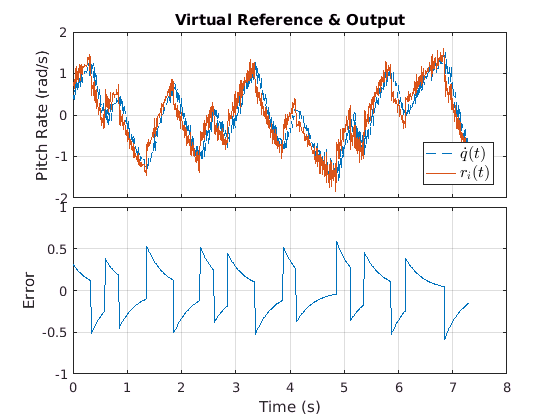

figure()
    ax1 = subplot(3, 1, [1 2]);
        plot(vrft_data.time, vrft_data.q_dot, '--', vrft_data.time, ri);
        legend({'$$\dot{q}(t)$$', '$$r_i(t)$$'}, 'Location', 'SouthEast', 'Interpreter', 'latex', 'FontSize', 12);
        title('Virtual Reference & Output');
        ylabel('Pitch Rate (rad/s)');
    ax2 = subplot(3, 1,3);
        plot(vrft_data.time, ei);
        ylabel('Error'); xlabel('Time (s)'); grid on;
        
condense_subplots_vertical([ax1, ax2]);

## Calculating The Output

The outer loop controls the pitch angle $\Theta$. This is not present in our data but we can get it by simply integrating the pitch rate ($\dot{q}$).

vrft_data.theta = lsim(integrator, vrft_data.q_dot, vrft_data.time);

## Producing the VRFT Controller

We can now run the VRFT engine using the PD controller class.

[~, outer_pd_params_orig] = VRFT1_ry_theta(...
    ri, vrft_data.theta, OuterReferenceModel_dt,  PDControllerClass_dt, [], [], []);

However, sometimes the controller will have a small but negative gain on the derivative comopnent. We need to zero it outto preserve the stability of the system.

fprintf('PID Controller params: Kp = %.3f, Kd = %.3f', ...
    outer_pd_params_orig(1), outer_pd_params_orig(2));

PID Controller params: Kp = 2.222, Kd = -0.155


outer_pd_params = [ 
    max(outer_pd_params_orig(1), 0) 
    max(outer_pd_params_orig(2), 0)
];

OptimalOuterController_dt = pid(...
    outer_pd_params(1), 0, outer_pd_params(2), Tf, Ts);
fprintf('Corrected PID Controller params: Kp = %.3f, Kd = %.3f', ...
    outer_pd_params(1), outer_pd_params(2));

Corrected PID Controller params: Kp = 2.222, Kd = 0.000

## Viewing The Results

We have the parameters for the discrete time PD controller at our disposal now but we need to produce a continuous time controller since the quadcopter test harness is continuous time. We will however keep the discrete time controller as a safety check to ensure that no funky buisness happens in the ``continuasation`` process.

cloop = loopsens(integrator_dt * InnerLoop_VRFT_dt, OptimalOuterController_dt); 
OuterLoop_VRFT_dt = cloop.Ti;

Next we discretise the controller and calculate the continuous-time, closed loop complemetary sensitivity function

OptimalOuterController = d2c(OptimalOuterController_dt);

cloop = loopsens(integrator * InnerLoop_VRFT, OptimalOuterController);
OuterLoop_VRFT = cloop.Ti;

Now that we have a decent controller we can explore it's performance compared to the original $H_{\infty}$ controller.

To ensure that nothing has gone wrong we compare the outputs of the two controllers and the two systems

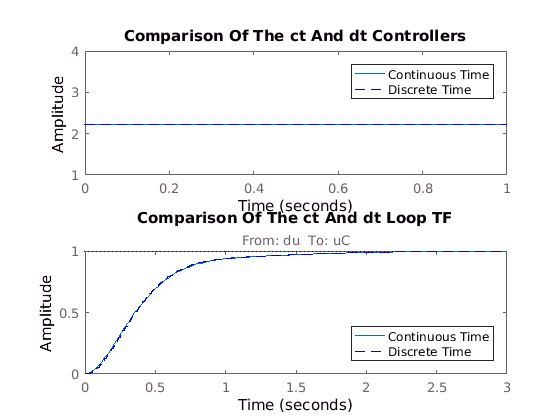

figure()
    subplot(2, 1, 1);
        step(OptimalOuterController, OptimalOuterController_dt, '--');
        legend('Continuous Time', 'Discrete Time');
        title('Comparison Of The ct And dt Controllers');
    subplot(2, 1, 2);
        step(OuterLoop_VRFT, OuterLoop_VRFT_dt, '--');
        legend('Continuous Time', 'Discrete Time', 'location', 'southEast');
        title('Comparison Of The ct And dt Loop TF');        

Luckily, everything looks good. We can move on.

## Performance Analysis

Let's explore the differences between the reference model and it's actual realisation:

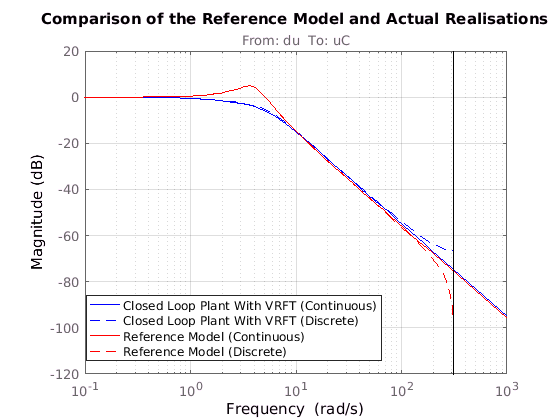


    
figure()
    bode(OuterLoop_VRFT, 'b', OuterLoop_VRFT_dt, 'b--', ...
         OuterReferenceModel, 'r', OuterReferenceModel_dt, 'r--', bode_no_phase);
    title('Comparison of the Reference Model and Actual Realisations');
    legend({ 'Closed Loop Plant With VRFT (Continuous)'
             'Closed Loop Plant With VRFT (Discrete)'
             'Reference Model (Continuous)'
             'Reference Model (Discrete)'
           }, 'location', 'SouthWest');
    grid on;    

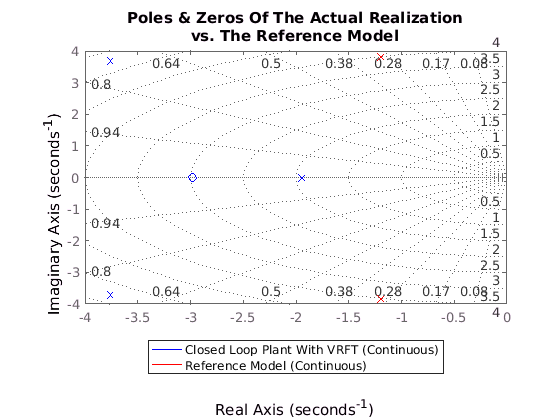

    
figure()
    pzmap(OuterLoop_VRFT, 'b', OuterReferenceModel, 'r');
    title({'Poles & Zeros Of The Actual Realization' 'vs. The Reference Model'});
    legend({ 'Closed Loop Plant With VRFT (Continuous)', 
             'Reference Model (Continuous)' }, 'location', 'SouthOutside');
    grid on;

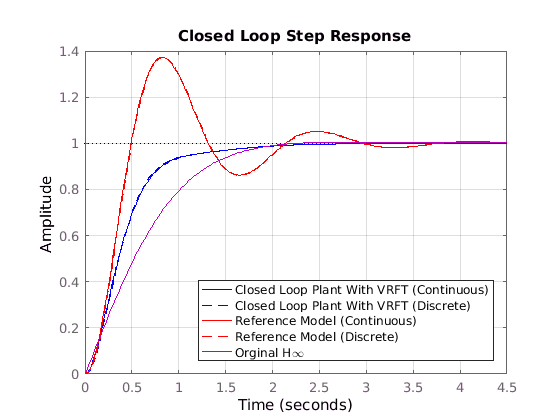

    
figure()
    step(OuterLoop_VRFT, 'b', OuterLoop_VRFT_dt, 'b--', ...
         OuterReferenceModel, 'r', OuterReferenceModel_dt, 'r--', ...
         OuterLoop_Hinf, 'm');
    title('Closed Loop Step Response'); 
    legend({ 'Closed Loop Plant With VRFT (Continuous)'
             'Closed Loop Plant With VRFT (Discrete)'
             'Reference Model (Continuous)'
             'Reference Model (Discrete)'
             'Orginal H\infty'
           }, 'location', 'SouthEast');
    grid on;      

We can also check the behaviour of the system on a more complex input sequence:

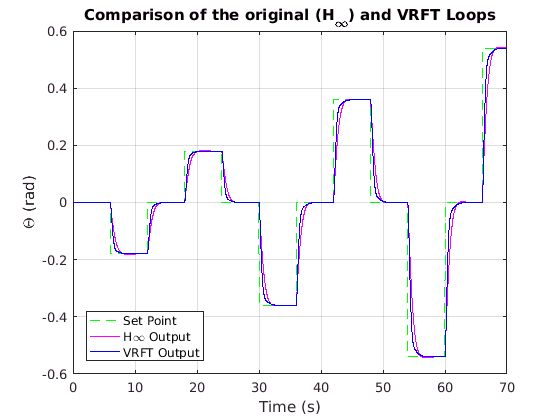

hinf_sr = lsim(OuterLoop_Hinf, PitchTestSequence.Theta, PitchTestSequence.Time);
vrft_sr = lsim(OuterLoop_VRFT, PitchTestSequence.Theta, PitchTestSequence.Time);

figure() 
    plot(PitchTestSequence.Time, PitchTestSequence.Theta, 'g--', ...
         PitchTestSequence.Time, hinf_sr, 'm', ...
         PitchTestSequence.Time, vrft_sr, 'b');
    title('Comparison of the original (H_\infty) and VRFT Loops');
    legend('Set Point', 'H\infty Output', 'VRFT Output', 'Location', 'SouthWest');
    xlabel('Time (s)'), ylabel('\Theta (rad)'); grid on; 

## Conclusion

In this case too the continuous and discrete time systems are close enough to be interchangeable. The PD parameters of the controllers are:

[Kp, Ki, Kd, Tf] = piddata(OptimalOuterController);
    
fprintf('PID Controller Parameters');

PID Controller Parameters

fprintf('');
fprintf('╔═════════════════════════╦══════════╦══════════╗');

╔═════════════════════════╦══════════╦══════════╗

fprintf('║                         ║    Kp    ║    Kd    ║');

║                         ║    Kp    ║    Kd    ║

fprintf('╠═════════════════════════╬══════════╬══════════╣');

╠═════════════════════════╬══════════╬══════════╣

fprintf('║ Discrete-Time Original  ║ %8.4f ║ %8.4f ║', ... 
    outer_pd_params_orig(1), outer_pd_params_orig(2));

║ Discrete-Time Original  ║   2.2225 ║  -0.1548 ║

fprintf('╠═════════════════════════╬══════════╬══════════╣');

╠═════════════════════════╬══════════╬══════════╣

fprintf('║ Discrete-Time Corrected ║ %8.4f ║ %8.4f ║', ... 
    outer_pd_params(1), outer_pd_params(2));

║ Discrete-Time Corrected ║   2.2225 ║   0.0000 ║

fprintf('╠═════════════════════════╬══════════╬══════════╣');

╠═════════════════════════╬══════════╬══════════╣

fprintf('║ Continuous Time         ║ %8.4f ║ %8.4f ║', Kp, Kd);

║ Continuous Time         ║   2.2225 ║   0.0000 ║

fprintf('╚═════════════════════════╩══════════╩══════════╝');

╚═════════════════════════╩══════════╩══════════╝

Even though our inner controller still has some issues the outer controller does a stellar job at compensating for them and delivers great performance. We just need to see how high it can go on the real system.

Let's chech out the poles of the two systems

fprintf('\nInnerReferenceModel information:');


InnerReferenceModel information:

damp(OuterReferenceModel)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -1.20e+00 + 3.82e+00i     3.00e-01       4.00e+00         8.33e-01    
 -1.20e+00 - 3.82e+00i     3.00e-01       4.00e+00         8.33e-01    



fprintf('\nInnerLoop_VRFT information:');


InnerLoop_VRFT information:

damp(OuterLoop_VRFT)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -1.95e+00                 1.00e+00       1.95e+00         5.14e-01    
 -3.76e+00 + 3.69e+00i     7.14e-01       5.27e+00         2.66e-01    
 -3.76e+00 - 3.69e+00i     7.14e-01       5.27e+00         2.66e-01    
